# Visualizing the Pressure Solution

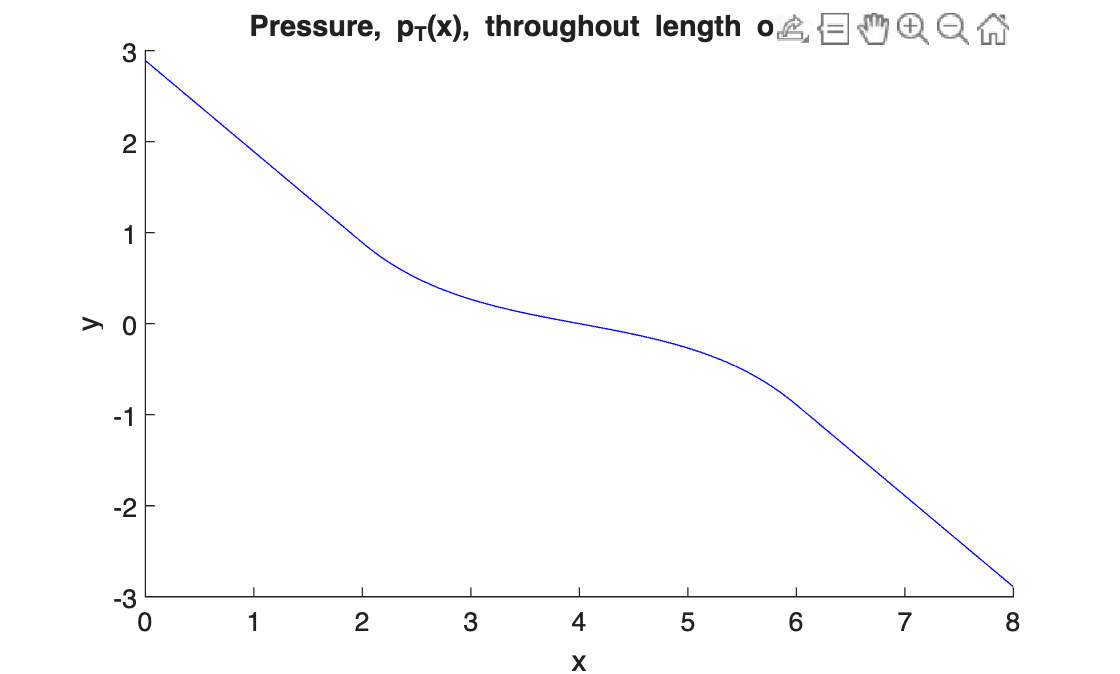

% Parameters
Da = 0.4;
H = 1;
mu = 1;
alpha = sqrt(3*mu/H^3 * Da);
H = 1; 
c = 2*H;
L = 4;
G = 1;
pL = -G/alpha * tanh(alpha*L/2);
gamma = pL/sinh(alpha*L/2);
xm = (L+2*c)/2;

p = @(x,y,xm,gamma, alpha,H) gamma * (sinh(alpha*(x-xm)).*cos(alpha*(y-H))/cos(alpha*H));
figure
hold on
x = linspace(c,L+c,100);
pData = p(x,2*H,xm,gamma,alpha,H);
plot(x,pData,'b');

xL = linspace(0,c,100);
xR = linspace(L+c,L+2*c,100);
pc  = gamma*sinh(alpha*(c-xm));
pLc = gamma*sinh(alpha*(L+c-xm));

plot(xL,pc  - G*(xL-c),'b')
plot(xR,pLc - G*(xR-(L+c)),'b')

xlabel('x')
ylabel('y')
title('Pressure, p_T(x), throughout length of channel')

Looking at the graph, this doesn't seem correct. We have matched the slopes at the discontinuities, but overall, it doesn't look like the pressure graphs in CP's paper.

% Check pressure
syms x y alpha gamma xm H;
psym = p(x,y,xm,gamma,alpha,H);
psym_xx = diff(psym,x,2);
psym_yy = diff(psym,y,2);
checkZero = psym_xx + psym_yy

$$checkZero = 0$$

pT = @(x) gamma*sinh(alpha*(x-xm));
psymTop = subs(psym,'y',2*H)

$$psymTop = \gamma \,\sinh\left(\alpha \,\left(x-\mathrm{xm}\right)\right)$$

psymBot = subs(psym,'y',0)

$$psymBot = \gamma \,\sinh\left(\alpha \,\left(x-\mathrm{xm}\right)\right)$$